% #01
clear
format short
digits(3)
syms t
u=10*sin(100*t+90*pi/180)

$$u = 10\,\sin\left(100\,t+\frac{\pi }{2}\right)$$

ud=10*exp(1j*(100*t+pi/2))

$$ud = 10\,{\mathrm{e}}^{100\,t\,\mathrm{i}+\frac{\pi \,\mathrm{i}}{2}}$$

Ud_m=10*exp(1j*pi/2)

Ud_m =    0.0000 +10.0000i


Ud=Ud_m/sqrt(2)

Ud =    0.0000 + 7.0711i


% #02
Id_m=80-60j % мА

Id_m =   80.0000 -60.0000i


Ip_m=vpa([abs(Id_m),angle(Id_m)*180/pi])

$$Ip\_m = \left(\begin{array}{cc} 100.0 & -36.9 \end{array}\right)$$

Id=Id_m/sqrt(2)

Id =   56.5685 -42.4264i


x=[0,real(Id)]

x =          0   56.5685


y=[0,imag(Id)]

y =          0  -42.4264


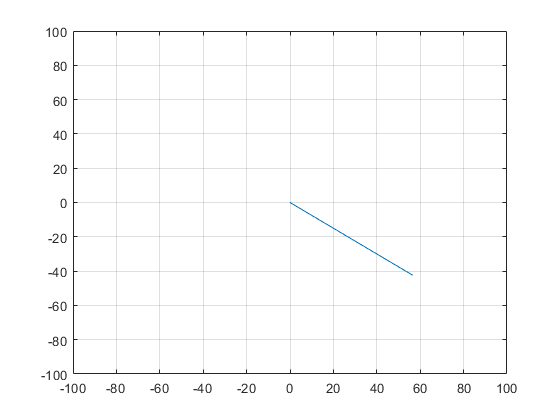

plot(x,y)
grid
xlim([-100,100])
ylim([-100,100])

% #03
clear
Id=0.05-0.087j

Id =    0.0500 - 0.0870i


Ud=200*exp(30*pi/180*1j)

Ud =    1.7321e+02 + 1.0000e+02i


Z=vpa(Ud/Id)

$$Z = -3.95+2000.0\,\mathrm{i}$$

x=[0,real(Id)]*10

x =          0    0.5000


y=[0,imag(Id)]*10

y =          0   -0.8700


plot(x,y)
grid
xlim([-1,1])
ylim([-1,1])
x=[0,real(Ud)]/1000

x =          0    0.1732


y=[0,imag(Ud)]/1000

y =          0    0.1000


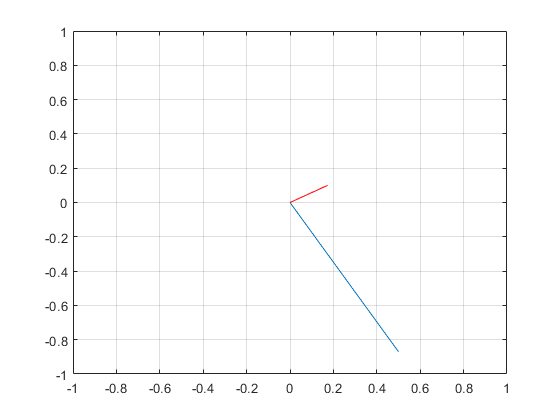

hold on
plot(x,y,'r')
hold off

% #04
clear
U=10 % В

U = 10

I=2 % А

I = 2

phi=-30 % град

phi = -30

Ud=U*exp(1j*phi*pi/180)

Ud =    8.6603 - 5.0000i


Id=I*exp(1j*phi*pi/180)

Id =    1.7321 - 1.0000i


Z=Ud/Id

Z = 5

Y=Id/Ud

Y =    0.2000 - 0.0000i


% #05
syms t
u=100*sin(314*t+90*pi/180)

$$u = 100\,\sin\left(314\,t+\frac{\pi }{2}\right)$$

i=0.2*sin(314*t+53*pi/180)

$$i = \frac{\sin\left(314\,t+\frac{53\,\pi }{180}\right)}{5}$$

Ud_m=100*exp(1j*pi/2)

Ud_m =    6.1232e-15 + 1.0000e+02i


Id_m=0.2*exp(1j*53*pi/180)

Id_m =    0.1204 + 0.1597i


Ud=Ud_m/sqrt(2)

Ud =    0.0000 +70.7107i


Id=Id_m/sqrt(2)

Id =    0.0851 + 0.1129i


Z=vpa(Ud/Id)

$$Z = 399.0+301.0\,\mathrm{i}$$

Y=vpa(Id/Ud)

$$Y = 0.0016-0.0012\,\mathrm{i}$$

Sd=vpa(Ud*Id')

$$Sd = 7.99+6.02\,\mathrm{i}$$

S=abs(Sd)

$$S = 10.0$$

% #06
clear
U=100 % В

U = 100

R=80 % Ом

R = 80

X_L=100 % Ом

X_L = 100

X_C=60 % Ом

X_C = 60


% а)
Z=R+1j*X_L-1j*X_C

Z =   80.0000 +40.0000i


Y=1/Z

Y =    0.0100 - 0.0050i


% б)
Z=1/(1/R+1/(-1j*X_C))

Z =   28.8000 -38.4000i


Y=1/Z

Y =    0.0125 + 0.0167i


% в)
Z=1/(1/R+1/(1j*X_L))

Z =   48.7805 +39.0244i


Y=1/Z

Y =    0.0125 - 0.0100i


% #07
clear
U=100 % В

U = 100

R=10 % Ом

R = 10

X_L=10 % Ом

X_L = 10

X_C=10 % Ом

X_C = 10

Ud=U

Ud = 100

% Комплексные сопротивления
Z1=1j*X_L, Z2=R, Z3=-1j*X_C

Z1 =    0.0000 +10.0000i


Z2 = 10

Z3 =    0.0000 -10.0000i


Z23=Z2*Z3/(Z2+Z3), Zp2=vpa([abs(Z23),angle(Z23)*180/pi])

Z23 =    5.0000 - 5.0000i


$$Zp2 = \left(\begin{array}{cc} 7.07 & -45.0 \end{array}\right)$$

Z=Z1+Z23, Zp=vpa([abs(Z),angle(Z)*180/pi])

Z =    5.0000 + 5.0000i


$$Zp = \left(\begin{array}{cc} 7.07 & 45.0 \end{array}\right)$$

% Ток на входе цепи
Id=Ud/Z, Ip=vpa([abs(Id),angle(Id)*180/pi])

Id =   10.0000 -10.0000i


$$Ip = \left(\begin{array}{cc} 14.1 & -45.0 \end{array}\right)$$

% Напряжение на уч. L
Ud_L=vpa(Id*Z1), Up_L=vpa([abs(Ud_L),angle(Ud_L)*180/pi])

$$Ud\_L = 100.0+100.0\,\mathrm{i}$$

$$Up\_L = \left(\begin{array}{cc} 141.0 & 45.0 \end{array}\right)$$

% Напряжение на участке RC
Ud_RC=vpa(Id*Z23), Up_RC=vpa([abs(Ud_RC),angle(Ud_RC)*180/pi])

$$Ud\_RC = -100.0\,\mathrm{i}$$

$$Up\_RC = \left(\begin{array}{cc} 100.0 & -90.0 \end{array}\right)$$

Ud_L+Ud_RC

$$ans = 100.0$$

% Токи ветвей
Id_R=vpa(Ud_RC/Z2), Ip_R=vpa([abs(Id_R),angle(Id_R)*180/pi])

$$Id\_R = -10.0\,\mathrm{i}$$

$$Ip\_R = \left(\begin{array}{cc} 10.0 & -90.0 \end{array}\right)$$

Id_C=vpa(Ud_RC/Z3), Ip_L=vpa([abs(Id_C),angle(Id_C)*180/pi])

$$Id\_C = 10.0$$

$$Ip\_L = \left(\begin{array}{cc} 10.0 & 0 \end{array}\right)$$

% Действующие значения токов ветвей
I=Ip(1),I_R=Ip_R(1), I_C=Ip_L(1)

$$I = 14.1$$

$$I\_R = 10.0$$

$$I\_C = 10.0$$

Im_R=vpa(I_R*sqrt(2)),Im_C=vpa(I_C*sqrt(2))

$$Im\_R = 14.1$$

$$Im\_C = 14.1$$

syms omega t
i1=Im_R*sin(omega*t-pi/2)

$$i1 = -14.1\,\sin\left(\frac{\pi }{2}-\omega \,t\right)$$

i2=Im_C*sin(omega*t)

$$i2 = 14.1\,\sin\left(\omega \,t\right)$$

S=Ud*Id'

S =    1.0000e+03 + 1.0000e+03i


Sd_Z=I^2*Z1+I_R^2*Z2+I_C^2*Z3

$$Sd\_Z = 1000.0+1000.0\,\mathrm{i}$$

x=[0,real(Id)]

x =      0    10


y=[0,imag(Id)]

y =      0   -10


plot(x,y,'b')
xlim([-15,15])
ylim([-15,15])
hold on
x=[0,real(Id_R)]

$$x = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

y=[0,imag(Id_R)]

$$y = \left(\begin{array}{cc} 0 & -10.0 \end{array}\right)$$

plot(x,y,'b')
x=[0,real(Id_C)]

$$x = \left(\begin{array}{cc} 0 & 10.0 \end{array}\right)$$

y=[0,imag(Id_C)]

$$y = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

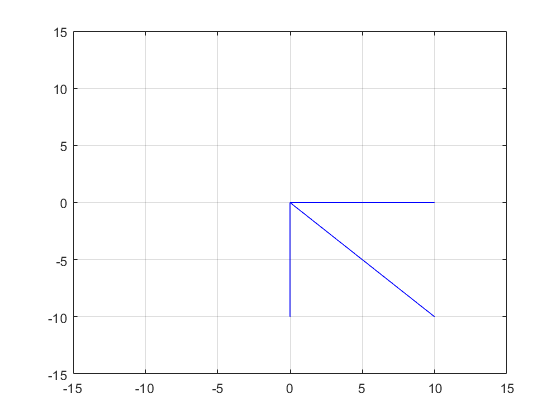

plot(x,y,'b')
grid
hold off

x=[0,real(Ud)]

x =      0   100


y=[0,imag(Ud)]

y =      0     0


plot(x,y,'r')
xlim([-150,150])
ylim([-150,150])
hold on
x=[0,real(Ud_L)]

$$x = \left(\begin{array}{cc} 0 & 100.0 \end{array}\right)$$

y=[0,imag(Ud_L)]

$$y = \left(\begin{array}{cc} 0 & 100.0 \end{array}\right)$$

plot(x,y,'r')
x=[0,real(Ud_RC)]

$$x = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

y=[0,imag(Ud_RC)]

$$y = \left(\begin{array}{cc} 0 & -100.0 \end{array}\right)$$

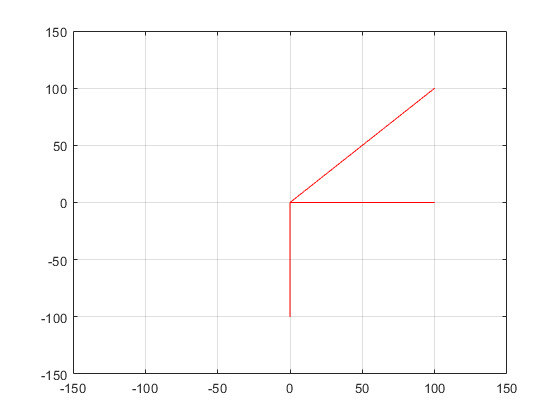

plot(x,y,'r')
grid
hold off